d = gpuDeviceCount

d = 1

d = gpuDevice

d =   CUDADevice - 属性:

                      Name: 'GeForce GTX 970'
                     Index: 1
         ComputeCapability: '5.2'
            SupportsDouble: 1
             DriverVersion: 9.1000
            ToolkitVersion: 8
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 4.2950e+09
           AvailableMemory: 3.4806e+09
       MultiprocessorCount: 13
              ClockRateKHz: 1253000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
            DeviceSelected: 1


gpuDevice([])

Deselecting: 1

ans =

     []




mgr = parallel.gpu.GPUDeviceManager.instance();
l1 = event.listener(mgr, 'DeviceSelected', @(src, data) fprintf('Selected: %d\n', data.DeviceIndex));
l2 = event.listener(mgr, 'DeviceDeselecting', @(src, data) fprintf('Deselecting: %d\n', data.DeviceIndex));
a1 = gpuArray(1:10);

Selected: 1


reset(mgr.SelectedDevice)

Deselecting: 1
Selected: 1


## for and parfor

tic
n = 200;
A = 500;
a = zeros(n);
for i = 1:n
    a(i) = max(abs(eig(rand(A))));
end
toc

时间已过 26.413459 秒。



tic
n = 200;
A = 500;
a = zeros(n);
parfor i = 1:n
    a(i) = max(abs(eig(rand(A))));
end
toc

时间已过 10.473370 秒。


gpu = gpuDevice();
fprintf('Using a %s GPU.\n', gpu.Name)

Using a GeForce GTX 970 GPU.


sizeOfDouble = 8; % Each double-precision number needs 8 bytes of storage
sizes = power(2, 14:28);


sendTimes = inf(size(sizes));
gatherTimes = inf(size(sizes));
for ii=1:numel(sizes)
    numElements = sizes(ii)/sizeOfDouble;
    hostData = randi([0 9], numElements, 1);
    gpuData = randi([0 9], numElements, 1, 'gpuArray');
    % Time sending to GPU
    sendFcn = @() gpuArray(hostData);
    sendTimes(ii) = gputimeit(sendFcn);
    % Time gathering back from GPU
    gatherFcn = @() gather(gpuData);
    gatherTimes(ii) = gputimeit(gatherFcn);
end

sendBandwidth = (sizes./sendTimes)/1e9;
[maxSendBandwidth,maxSendIdx] = max(sendBandwidth);
fprintf('Achieved peak send speed of %g GB/s\n',maxSendBandwidth)

Achieved peak send speed of 5.66631 GB/s


gatherBandwidth = (sizes./gatherTimes)/1e9;
[maxGatherBandwidth,maxGatherIdx] = max(gatherBandwidth);
fprintf('Achieved peak gather speed of %g GB/s\n',max(gatherBandwidth))

Achieved peak gather speed of 2.78722 GB/s


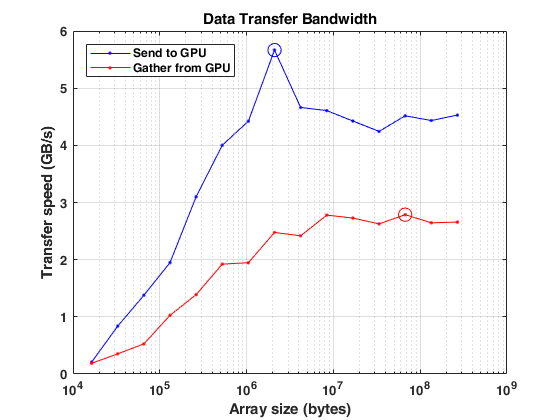

hold off
semilogx(sizes, sendBandwidth, 'b.-', sizes, gatherBandwidth, 'r.-')
hold on
semilogx(sizes(maxSendIdx), maxSendBandwidth, 'bo-', 'MarkerSize', 10);
semilogx(sizes(maxGatherIdx), maxGatherBandwidth, 'ro-', 'MarkerSize', 10);
grid on
title('Data Transfer Bandwidth')
xlabel('Array size (bytes)')
ylabel('Transfer speed (GB/s)')
legend('Send to GPU', 'Gather from GPU', 'Location', 'NorthWest')

memoryTimesGPU = inf(size(sizes));
for ii=1:numel(sizes)
    numElements = sizes(ii)/sizeOfDouble;
    gpuData = randi([0 9], numElements, 1, 'gpuArray');
    plusFcn = @() plus(gpuData, 1.0);
    memoryTimesGPU(ii) = gputimeit(plusFcn);
end
memoryBandwidthGPU = 2*(sizes./memoryTimesGPU)/1e9;
[maxBWGPU, maxBWIdxGPU] = max(memoryBandwidthGPU);
fprintf('Achieved peak read+write speed on the GPU: %g GB/s\n',maxBWGPU)

Achieved peak read+write speed on the GPU: 133.925 GB/s


memoryTimesHost = inf(size(sizes));
for ii=1:numel(sizes)
    numElements = sizes(ii)/sizeOfDouble;
    hostData = randi([0 9], numElements, 1);
    plusFcn = @() plus(hostData, 1.0);
    memoryTimesHost(ii) = timeit(plusFcn);
end

memoryBandwidthHost = 2*(sizes./memoryTimesHost)/1e9;
[maxBWHost, maxBWIdxHost] = max(memoryBandwidthHost);
fprintf('Achieved peak read+write speed on the host: %g GB/s\n',maxBWHost)

Achieved peak read+write speed on the host: 64.8357 GB/s



% Plot CPU and GPU results.
hold off

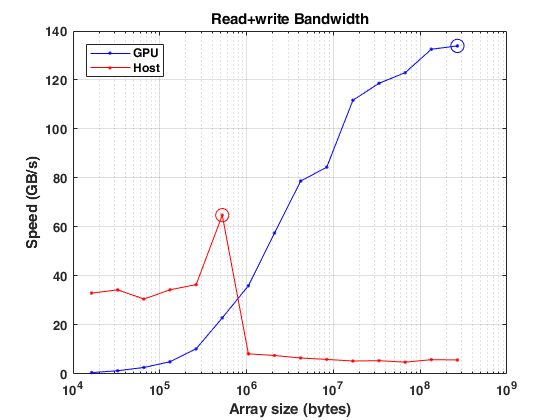

semilogx(sizes, memoryBandwidthGPU, 'b.-', ...
    sizes, memoryBandwidthHost, 'r.-')
hold on
semilogx(sizes(maxBWIdxGPU), maxBWGPU, 'bo-', 'MarkerSize', 10);
semilogx(sizes(maxBWIdxHost), maxBWHost, 'ro-', 'MarkerSize', 10);
grid on
title('Read+write Bandwidth')
xlabel('Array size (bytes)')
ylabel('Speed (GB/s)')
legend('GPU', 'Host', 'Location', 'NorthWest')

sizes = power(2, 12:2:24);
N = sqrt(sizes);
mmTimesHost = inf(size(sizes));
mmTimesGPU = inf(size(sizes));
for ii=1:numel(sizes)
    % First do it on the host
    A = rand( N(ii), N(ii) );
    B = rand( N(ii), N(ii) );
    mmTimesHost(ii) = timeit(@() A*B);
    % Now on the GPU
    A = gpuArray(A);
    B = gpuArray(B);
    mmTimesGPU(ii) = gputimeit(@() A*B);
end

An unexpected error occurred during CUDA execution. The CUDA error was:
the launch timed out and was terminated

出错 parallel.internal.gpu.timeit

出错 parallel.internal.gpu.timeit

出错 gputimeit (line 66)
t = parallel.internal.gpu.timeit(f,  num_outputs);

mmGFlopsHost = (2*N.^3 - N.^2)./mmTimesHost/1e9;
[maxGFlopsHost,maxGFlopsHostIdx] = max(mmGFlopsHost);
mmGFlopsGPU = (2*N.^3 - N.^2)./mmTimesGPU/1e9;
[maxGFlopsGPU,maxGFlopsGPUIdx] = max(mmGFlopsGPU);
fprintf(['Achieved peak calculation rates of ', ...
    '%1.1f GFLOPS (host), %1.1f GFLOPS (GPU)\n'], ...
    maxGFlopsHost, maxGFlopsGPU)

hold off
semilogx(sizes, mmGFlopsGPU, 'b.-', sizes, mmGFlopsHost, 'r.-')
hold on
semilogx(sizes(maxGFlopsGPUIdx), maxGFlopsGPU, 'bo-', 'MarkerSize', 10);
semilogx(sizes(maxGFlopsHostIdx), maxGFlopsHost, 'ro-', 'MarkerSize', 10);
grid on
title('Double precision matrix-matrix multiply')
xlabel('Matrix size (numel)')
ylabel('Calculation Rate (GFLOPS)')
legend('GPU', 'Host', 'Location', 'NorthWest')